%Carga de los archivos y datoa%
load input_p.txt
load input_p_2.txt
load input_p_3.txt
load target.txt
load target_2.txt
load target_3.txt
p = input_p_2;
t = target_2;
[num_p,R] = size(p);
[num_t,S] = size(t);
num_cls = num_t/2;
disp("El numero de rasgos es: "+R);

El numero de rasgos es: 2


disp("El numero de clases ingresadas es: "+ num_cls);

El numero de clases ingresadas es: 4


disp("El numero de neuronas necesarias es: "+ S);    

El numero de neuronas necesarias es: 2


% Matriz de pesos %
W = randi([-10,10],S,R);
disp(W)

    -8     9
    -2     6



%Calculo de el Bias%
b = randi([-10 10],S,1);
%Aqui empieza el aprendizaje
%Solicitamos el numero de iteraciones
CU=0;
max=input('Ingrese el numero de MAX_EPOCH:');
%Empieza el entrenamiento%
for i = 1:num_p
    figure(1)
    hold on
    grid on
    plot(p(i,1),p(i,2),'ko');
end   

for u=1:max
    bandera=0;
    disp("Epoca num: "+u);
    for i=1:num_p
        p_i = transpose(p(i,:));
        a_i = hardlim(W*p_i+b);
        e = (transpose(t(i,:))-a_i);
        W = W + ( e*(p(i,:) ));
        b = b + e;
        if e==0
           bandera=bandera+1;
        end
    end
    if bandera==num_p
        disp('Aprendizaje Correcto!!!');
        bandera = -1;
        break
    end
end%Fin del entrenamiento%

Epoca num: 1
Epoca num: 2
Epoca num: 3
Epoca num: 4


Aprendizaje Correcto!!!


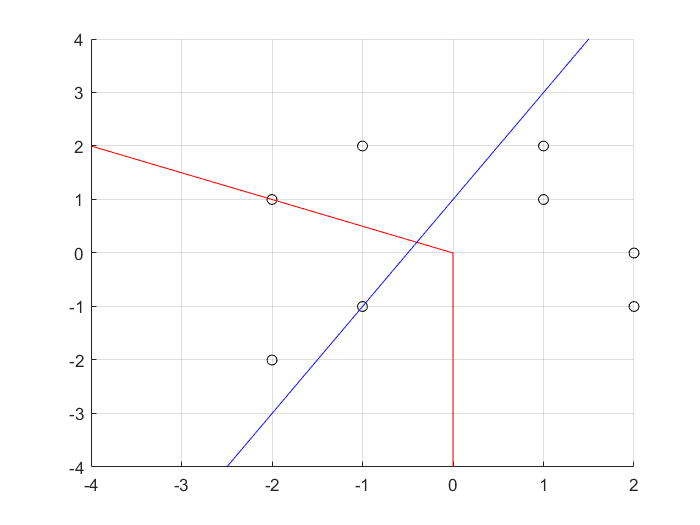


-4	2	
0	-4	
-2	
2	


%Desplegamos el menú dea acuerdo al resultado%
if bandera == -1    
    %Despleigue de la grafica%
    %rectas perpendiculares a los pesos sinápticos
    for i = 1:S
        w_i = W(i,:);
        b_i = transpose(b(:,1));
        P1=[0 0];P2=[w_i(1) w_i(2)];
        plot([P1(1) P2(1)],[P1(2) P2(2)],'r');
        X1 = (-1)*w_i(2);
        Y1 = w_i(1);
        P11=[0 0];P22=[X1 Y1];
        d = W(i);
        plot([P11(1) P22(1)]-(b_i(i)/W(i)),[P11(2) P22(2)],'b')
        plot(-[P11(1) P22(1)]-(b_i(i)/W(i)),-[P11(2) P22(2)],'b')
    end
    
    
    
    %Guardar valores de pesos y bias%
    fid = fopen('valores_finales_wyb.txt','w');
    [f,c]=size(W);
    for i=1:f
        for j=1:c
            fprintf(fid,'%d\t',W(i,j));
        end
        fprintf(fid,'\n');
    end
    [f,c]=size(b);
    for i=1:f
        for j=1:c
            fprintf(fid,'%d\t',b(i,j));
        end
        fprintf(fid,'\n');
    end
    fclose(fid);
    type('valores_finales_wyb.txt')
    %Validación del dataset%
    
    %Fin del programa%
    concluido = input("Teclee 1 para salir/0 para volver a intentar: ");    
else
    concluido = input("Aprendisaje fallido. Teclee 1 para salir/0 para volver a intentar");

end